# Clear console and workspace and add project root to path

close all;
project_root='/home/predator/swarmlab/';
addpath(genpath(project_root));

## Call parameters files and initialisation variables

DRONE_TYPE="quadcopter";
SIMULATION_REALISTIC= true;
ACTIVE_ENVIRONMENT = false;
DEBUG = false;
VIDEO = false;
CENTER_VIEW_ON_SWARM = true;
SWARM_ALGORITHM='olfati_saber';

fontsize = 12;
run('param_sim.m');
run('param_battery');
run('param_physics');
run('param_swarm');
%run('param_GS.m');

if DRONE_TYPE == "fixed_wing" || DRONE_TYPE == "quadcopter"
    run('param_drone.m'); 
elseif DRONE_TYPE == "point_mass"
    run('param_drone.m'); 
end
run('param_map');

if DRONE_TYPE == "point_mass"
   SWARM_VIEWER_TYPE = "agent";
elseif DRONE_TYPE == "quadcopter"
   SWARM_VIEWER_TYPE = "drone";
end

## Init Swarm object, Wind, Viewer and other variables

% Init swarm and set positions
x1=-100;
x2=200;
y1=200;
y2=600;
H=10;
swarm = Swarm();
swarm.algorithm = SWARM_ALGORITHM;
p_swarm.nb_agents=1;
swarmpos=[]


swarmpos =

     []



for i = 1 : p_swarm.nb_agents
    swarm.add_drone(DRONE_TYPE, p_drone, p_battery, p_sim, p_physics,map);
end

for j=1:4
    for i=1:5
        x=x1+(i-1)*((x2-x1)/5);
        y=y1+(j*(y2-y1)/4);
        z=H;
        k=5*(j-1)+i;
        swarmpos(:,k)=[x;y;z];
    end
end
swarm.set_pos(swarmpos)
% Init wind
wind = zeros(6,1); % steady wind (1:3), wind gusts (3:6)

% Init viewer
swarm_viewer = SwarmViewer(p_sim.dt_plot, CENTER_VIEW_ON_SWARM);
swarm_viewer.viewer_type = SWARM_VIEWER_TYPE;
states_handle = [];


## Main simulation loop

goal_reached = false;
disp('Type CTRL-C to exit');

Type CTRL-C to exit


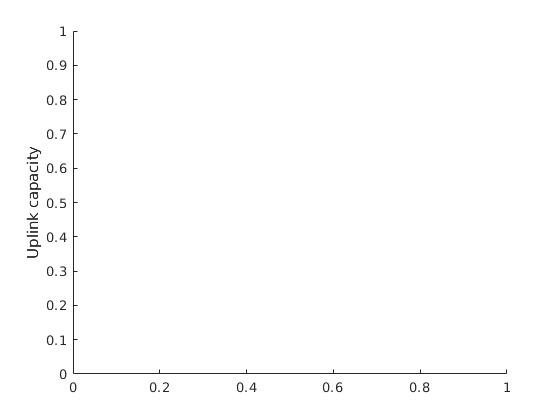

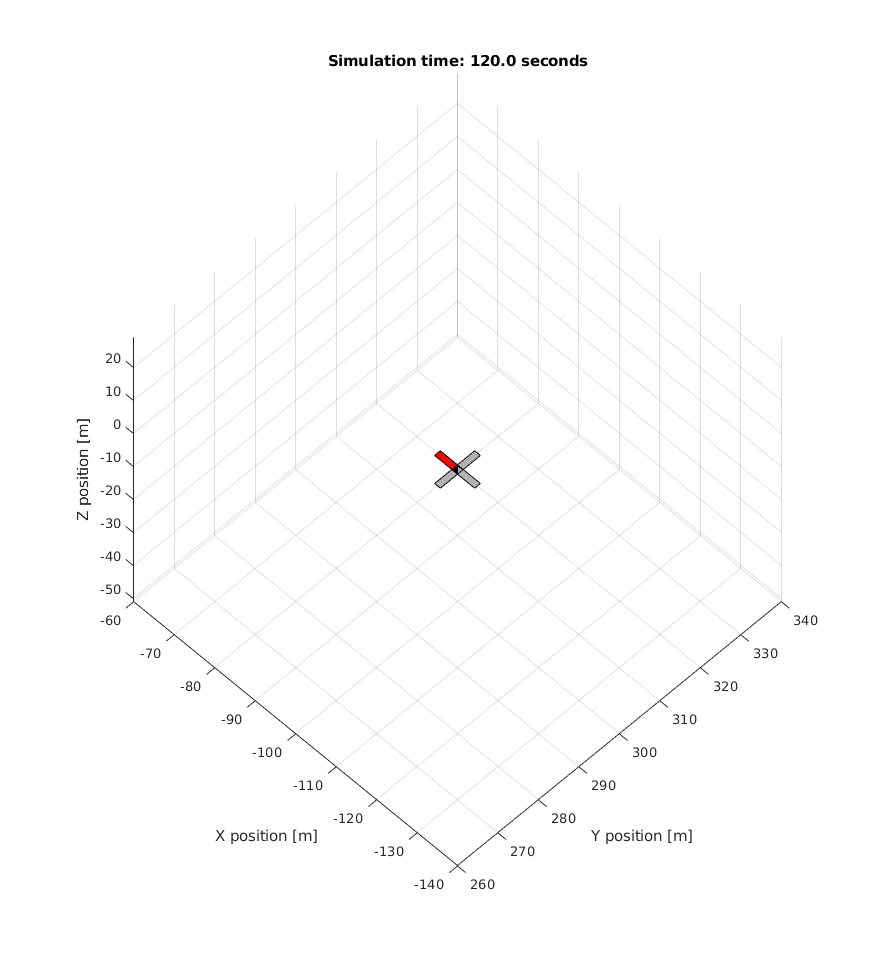

for time = p_sim.start_time:p_sim.dt:p_sim.end_time 
 
   
end